# PHY 329 Homework 1

## Ryan Schlimme (eid: rjs4499)

# Problem 5.7

## Part a)

format longg
xRange = -2: 0.01 : 6;       % define x range
fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;      % input polynomial

grid on;
figure(1); plot(xRange, fx(xRange));          % graph polynomial over range
hold on;
yline(0);
hold off

The graph seems to cross y = 0 three times, as we would expect from a third-order polynomial. If we zoom in iteratively on the three roots, we can provide an estimate of the roots.

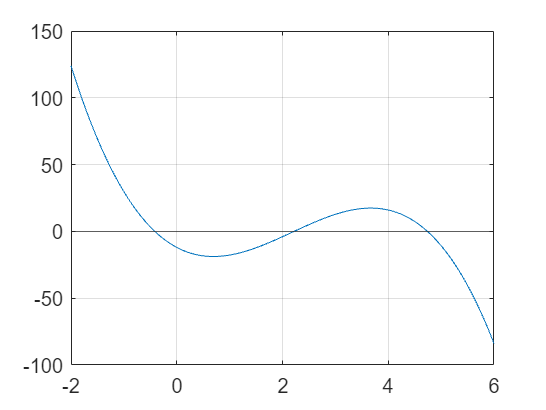

xRange = -2: 0.01 : 6;       % define x range
fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;      % input polynomial

grid on;

figure(2); plot(xRange, fx(xRange));          % graph polynomial over range
hold on;
xlim([-0.4191 -0.4107])
ylim([-0.113 0.149])
yline(0);
hold off

fx(-0.414675)

ans =      -0.000538234242057928


From visual inspection, there appears to be a root around x = -0.414675. If we plug this into our polynomial, we should expect to yield a result close to 0.

Our visual guess took several iterations of zooming in but yields a respectible guess.

Continuing this method, we can check for the other two roots.

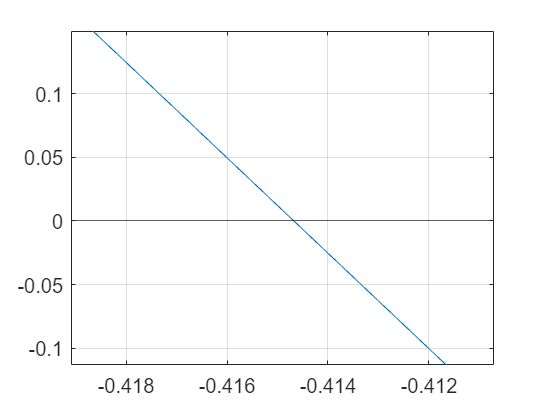

xRange = -2: 0.01 : 6;       % define x range
fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;      % input polynomial

grid on;

figure(3); plot(xRange, fx(xRange));          % graph polynomial over range
hold on;
yline(0);
xlim([2.21825 2.22119])
ylim([-0.045 0.047])
hold off



fx(2.2198)

ans =      -0.000334152577998736


Second root around x = 2.2198.

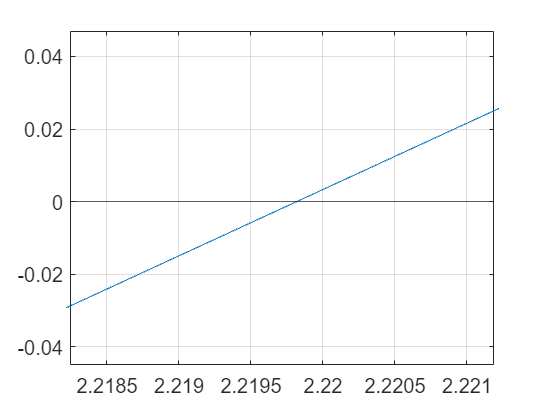

xRange = -2: 0.01 : 6;       % define x range
fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;      % input polynomial

grid on;

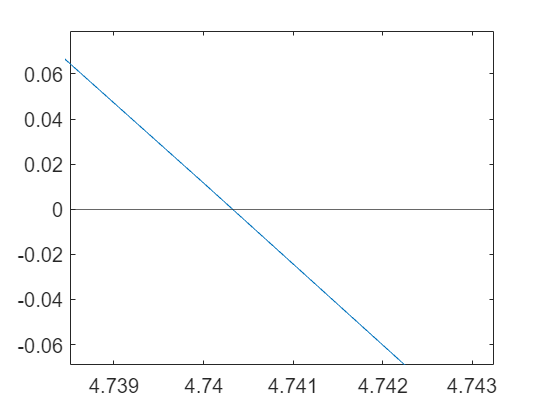



figure(4); plot(xRange, fx(xRange));          % graph polynomial over range
hold on;
yline(0);
xlim([4.73852 4.74324])
ylim([-0.069 0.079])
hold off


fx(4.740325)

ans =       2.35181900052339e-05


Third root around x = 4.740325.

## Part b)

fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;
xl = -1;
xu = 0;
es = 0.01;
[root, eval] = bisect(fx, xl, xu, es)

root =         -0.414703369140625


eval =       0.000521283354707691


Using bisection, our first root is x = -0.4147.

## Part c)

% xi+1 = xi - (f(xu)(xl - xu))/(f(xl)-f(xu))

% We use xl = -1, xu = 0, stopping criteria 1%

fx = @(x) -12 - 21*x + 18*x.^2 -2.75*x.^3;
xl = -1;
xu = 0;
es = 0.01;
xinitial = 0;

[rootregula, error] = regula(fx, xl, xu, es)

rootregula =         -0.414689411620145


error =      0


Using false position, our first root is x = -0.4147 with an error too small to display.

# Problem 5.8

We must determine the first nontrivial solution to sin(x) = x^2. If we rearrange this equation into 0 = x^2 - sin(x), we can solve by rootfinding.

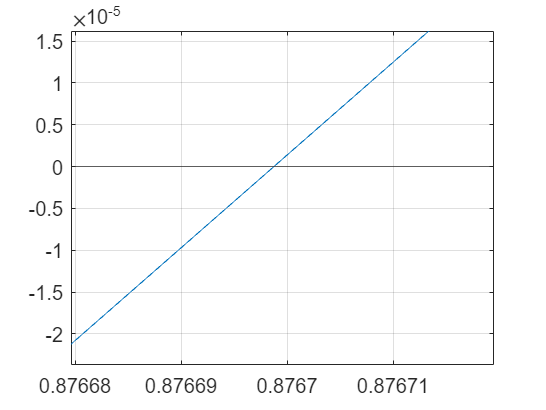

f = @(x) x.^2 - sin(x);
error = 0.02;

xRange = 0.5: 0.01 : 1;
figure(5); plot(xRange, f(xRange));
grid on;
hold on;
yline(0);
xlim([0.8766796 0.8767195])
ylim([-0.0000237 0.0000162])
hold off


f(0.876695)

ans =      -3.47657797906686e-05


Graphically, after zooming in heavily, we observe a root of xr = 0.876695 which quite accurately produces f(xr) = 0.

xl = 0.5;
xu = 1;
es = 0.02;
[root, eval] = bisect(f, xl, xu, es)

root =            0.8768310546875


eval =       0.000116783277113508


Using bisection, we achieve a root of 0.8768 rad with error 0.0001.

# Problem 5.9

We must determine the positive real root of ln(x^2) = 0.7

## Part a)

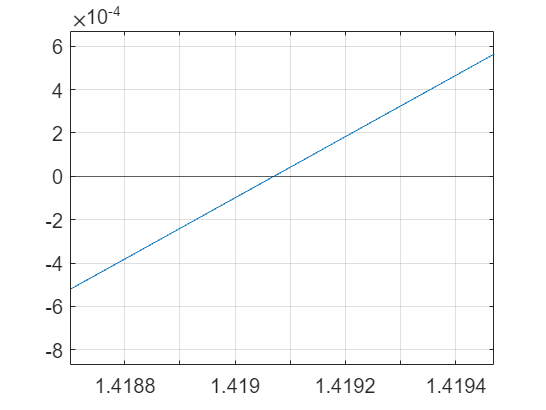

f = @(x) log(x.^2) - 0.7;
xRange = 1: 0.01 : 1.5;
figure(6); plot(xRange, f(xRange));
grid on;
hold on;
yline(0);
xlim([1.418703 1.419469])
ylim([-0.00087 0.00067])
hold off


f(1.4197)

ans =       0.000891163374782344


Graphically, it appears there is a root at 1.4197.

## Part b)

xl = 0.5;
xu = 2;
maxit = 3;
[root, eval] = bisect(f, xl, xu, maxit)

root =                  1.4140625


eval =       -0.00706646530758281


Using three iterations of bisection, we achieve a root of 1.4140625.

## Part c)

xl = 0.5;
xu = 2;

xnext = xu - (f(xu)*(xl-xu))/(f(xl)-f(xu))

xnext =           1.62870744823335


f(xnext)

ans =          0.275573447405012


f(xu)

ans =          0.686294361119891


xu = xnext

xu =           1.62870744823335



xnext = xu - (f(xu)*(xl-xu))/(f(xl)-f(xu))

xnext =           1.49701430202987


f(xnext)

ans =          0.106945318372039


f(xu)

ans =          0.275573447405012


xu = xnext

xu =           1.49701430202987



xnext = xu - (f(xu)*(xl-xu))/(f(xl)-f(xu))

xnext =            1.4483985429092


ans =         0.0409169858171372


ans =          0.106945318372039


With three iterations of Regula-Falsi, we arrive at a root of x = 1.448. Evidently, Regula-Falsi requires more iterations for this type of function.

# Problem 5.19

f = @(x) (x.^2 + 0.85.^2).^(3/2)*F*4*pi*epsilon/q/Q - x;
F = 1.25;
epsilon = 8.9e-12;
q = 2e-5;
Q = q;


fzero(f, 0.2)

ans =          0.241042736197939


fzero(f, 1)

The distances which solve the equation given the parameters are x = 0.2410 m and x = 1.2913 m.

# Problem 5.15

Using bisection, solve for when the derivative is 0. Then, substitute into the original equation to determine the value of max deflection given the parameters.

deriv = @(x) 2.5/(120*E*I*L)*(-5*x.^4+6*L.^2*x.^2-L.^4);
f = @(x) w/(120*E*I*L)*(-x.^5+2*L.^2*x.^3-L.^4*x);

L = 600;
E = 50000;
I = 30000;
w = 2.5;

root = fzero(deriv, 270)

Error using PHY_329_HW1>bisect
no sign change

fzero(deriv, 600)

f(root)

The two places where the derivative is 0 are x = 268.32816 cm and x = 600 cm. The latter of the two is nonphysical sense that is the end of the beam. Plugging this root into the original formula, we get a maximum deflection of -0.51519 cm.

Since this fourth order polynomial does not cross the y-axis (it merely touches it at four points), we cannot use bisection.

# Problem 5.24

Use b

# Define Our Functions

% bisect function

function [root, fx, ea, iter] = bisect(func, xl, xu, es, maxit, varargin)
if nargin<3, error('at least 3 input args required'), end
test = func(xl, varargin{:})*func(xu, varargin{:});
if test>0, error('no sign change'), end
if nargin<4 || isempty(es), es = 0.0001; end
if nargin<5 || isempty(maxit), maxit = 50; end
iter = 0; xr = xl; ea = 100;
while (1)
    xrold = xr; xr = (xl + xu)/2;
    iter = iter + 1;
    if xr ~= 0, ea = abs((xr - xrold)/xr)*100; end
    test = func(xl, varargin{:})*func(xr, varargin{:});
    if test <0
        xu = xr;
    elseif test > 0
        xl = xr;
    else
        ea = 0;
    end
    if ea <= es || iter >= maxit, break, end
end
root = xr; fx = func(xr, varargin{:});
end

% regula falsi
function [root, err] = regula(f, x0, x1, epsilon)
err=abs(x1-x0);
 %Formula: x2=x1-((x1-x0)/(f(x1)-f(x0)))*f(x1);
 if f(x0)*f(x1)>0 
    disp('Enter valid interval !!!');
    return
 else
%fprintf('\n x0 \t \t  x1 \t \t x2 \t \t f(x0) \t\t f(x1) \t\t  f(x2)');     
    while err > epsilon
        x2=x1-((x1-x0)/(f(x1)-f(x0)))*f(x1);
        root=x2;
    %fprintf('\n %0.4f \t %0.4f \t %0.5f \t %0.4f \t %0.4f\t %0.4f',x0,x1,x2,f(x0),f(x1),f(x2));
        if f(x1)*f(x2)<0
            x1=x2;
        else
            x0=x2;
        end
       err=abs(x0-x1);
    end
 end
end